# Accel World Agent Simulation, MATLAB Test Type

Goal:  Analyze the formation of Brain Burst within the Accel World universe, and attempt to find what parameters allow such an acceleration game to stablize over time.  What make BB2039 different from AA2038 and CC2040?  Can we manipulate settings such that we are able to reach level 4 and unlock the Unlimited Neutral Field?  What causes the system to break down?  

Thus, the search for a simulation of Brain Burst began.  The goal of this document is to explain my process and my code such that it is easier to understand and have more people participate in.  I try to comment my code pretty well, but there's a lot more that can be said here, I think, so I'm going to expand it out as much as I can.  This is written in MATLAB, so it is a bit weird and hacky at times.

This script will probably get super bloated if it is actually run as a live script, so all edits and actual simulations should be done in the script file, Mainsim.m.

## Definition of Parameters

In the first section, we are going to define our parameters that we are going to mainly vary.  We collect all of them here as to more easily be able to track them and their impact on the simulation.  All of these parameters are recorded in the README file in each 'SavedSims' folder.

### Global

These parameters affect global things.  They are mainly the random number generator seed for reproducability, and the maximum number of rounds we will simulate.  The goal of having a limit is to more effectively use our time, as longer simulations take a lot longer (no real surprise there). We can add other exit conditions later, but this is our most generic one.

### makePlayer - Player Creation

This function creates new players, which is our main source of Burst Points before the UNF.

We have 2 methods for experience, a created parameter that states how good a player is at the game.  This is a major factor in a player's win chance, and one of the more defining features for Brain Burst, so both the initial experience and its growth is important for how the simulation behaves.

The Continuous distrobution generates a random number between 0 and 1 and multiplies it by expMax.  Because of the way MATLAB generates random numbers, there are $2^{52}$ possilibites, so when scaled from 0 to expMax (eg 10), there are more than are discernable by eye.

The Discrete distrobution generates a random integer on the interval expRange, which creates a much more noticeable gradient.  I shift away from the discrete option because it looks less natural on a graph, and is not representative of the real world continuous levels of experience people have, nor the non-integer experience they gain over time.

valDistro and satDistro are for normalizing the color space, but that's another discussion.  Basically, color is a 3 dimensional vector space, but the BB color wheel shown by Kuroyukihime is really 2 dimensional.  More on that in the makePlayer function description section though.

Moral Booster isn't fully implemented into the simulation yet, but it is the morality of the player.  A lower morality index would mean that they are more likely to commit immoral acts.  The primary example of this would be IRL PK'ing, trapping someone and then direct dueling them until they lose all their points.  The other example that would have a big effect in the early days was Originators who would install BB on a player and then duel them to completely exhaust their points without teaching them how to play the game.  This could be a critical way to introduce points into the game, but hasn't been implemented yet because I'm too optimistic, and I'm not sure what the chance function for it should be yet.

### duel - Simulate Duels

This is the bread and butter of Brain Burst, the battle.  In terms of parameters, most deal with how points are distrobuted.

expMod is a modifier to how much each player learns from the battle and then supplements their own exp.  This has to be kept small so that we don't see an explosion of exp for the higher level players that makes it impossible to break into the game if you start later.  Another thing that helps to discourage that is that each player learns a percentage of the other's experience, since you would learn from how well the other person fights, and a huge mismatch in ability would not teach the more able player much.

drawTol is the tolerance for a draw, how close do the calculated win chance's need to be to consider it a draw?  This is pretty small, since most win rates are relatively small, and the chance of a draw is pretty uncommon in Brain Burst as well, except when two players just make a duel to talk (@Haruyuki).

highWinTrans and lowWinTrans are both functions of how many points are transfered at the end of a duel.  Since we only deal with integer points, we round them.  If a higher level player wins, this is the expected outcome so there is a smaller number of points transfered.  This decreases from 10, the standard to basically just one.  I think if the level difference is more than 6 or so, no points are transfered at all (from Silver Crow and Aqua Current's adventure), but that hasn't been implemented yet since there are no tag-team duels or players getting to level 6 or 7 yet.  If the lower levelled player wins, this is the unexpected outcome, so the lower levelled player gets more points.  From Crow's first fight against Ash, this seems to scale with level difference, as outlined below.  If the players are equal level, they just exchange 10 points, and if there is a draw, no points are transfered..  To summarize, $P_{\mathrm{high}} =\frac{10}{1+\mathrm{lvlDiff}},P_{\mathrm{low}} =10\left(1+\mathrm{lvlDiff}\right)$.  This functions are continuous at all points.

lvlGain is a modifier of how much level affects win chance.  This parameter was added because higher level players would start losing streaks and be unable to recover their BP for some very talented level 1'ers.  This is an actual mechanic though, as each level up grants the player a bonus which makes them stronger in combat.  This solved the problem, but the exact value of the function is still up for debate.

For example, we can graph the point exchange versus level difference and player level.

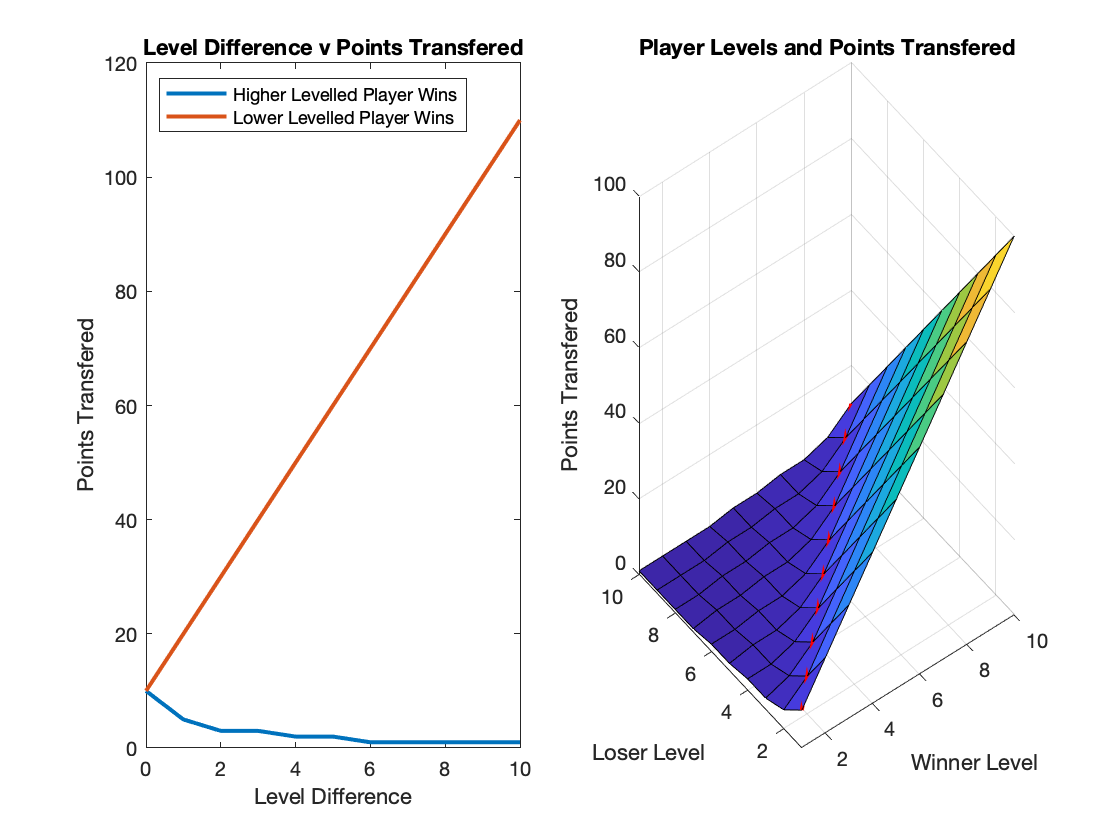

figure; 
subplot(1,2,1)%lvldiff
x = -0:10;
plot(x,round(10./(1+x)),'LineWidth',2)
hold on
plot(x,10*(1+x),'LineWidth',2)
xlabel('Level Difference'); ylabel('Points Transfered');
title('Level Difference v Points Transfered');
legend({'Higher Levelled Player Wins','Lower Levelled Player Wins'},...
    'Location','northwest')

subplot(1,2,2); %for all levels
lvlWinner = 1:10; lvlLoser = 1:10; %levels of winners/losers
[WW, LL] = meshgrid(lvlWinner,lvlLoser); %meshgrid
points = zeros(10); %preallocate
for indW = lvlWinner
    for indL = lvlLoser
        lvlDiff = indW-indL;
        if(lvlDiff > 0 ) %W expected
            points(indW,indL) = round(10/(1+lvlDiff));
        elseif(lvlDiff == 0) %same level
            points(indW,indL) = 10;
        elseif(lvlDiff < 0) %upset, L expected
            points(indW,indL) = (10*(1-lvlDiff));
        end
    end %loser lvl
end %winner lvl
surf(WW,LL,points);
hold on
plot3([1, 10], [1 10],[10 10],'r','LineWidth',2)
hidden off
xlim([1 10]); ylim([1 10])
title('Player Levels and Points Transfered');
xlabel('Winner Level'); ylabel('Loser Level'); 
zlabel('Points Transfered');

### killEm

Function to kill players, but there are no parameters here.

### lvlUp

Function to level up players who are elgible.

points is the number required to level up from each level.  These are from the JP wiki, which seems like the most reputable source.  We can't level up from 9->10 yet, but this simulation is not built to simulate that much life out of Brain Burst.

margin is how much of a buffer a player has to have before they level up.  Since leveling up eats that number of points, players need to have enough to continue playing afterward.  This used to be 1.25, but a couple players died shortly after reaching level 3, so it was increased.  It would vary by player, but keeping it constant makes the simulation simpler.

(As a thought, this could have a random component, maybe...)

### makeBabes

Function to create new players (babies).  This function just calls makePlayer, so it's basically only a frequency and elgibility checker.

chanceFcn is the probability that a new player will be created as the child of an elgible player.  When it is equal to itself, a new child is born.  This decreased over time, since logically it would be harder and harder to find new compatible kids IRL.  Basically, it generates a random integer with a maximum of $\left(\frac{\mathrm{rounds}}{30}+1\right)$.  As the simulation runs for longer, rounds gets larger and larger.  We add 1 so that we never get a max value of zero, but it essentially is always equal in the early rounds, not that they can make kids at round 30 though.  We can graph the chance that it is equal to itself as well. 

Since we usually don't get players to level 2 until around round 100, it might be worth modifying the function to $\left(\frac{\left(\mathrm{rounds}-100\right)}{30}+1\right)$ or some variation therein.

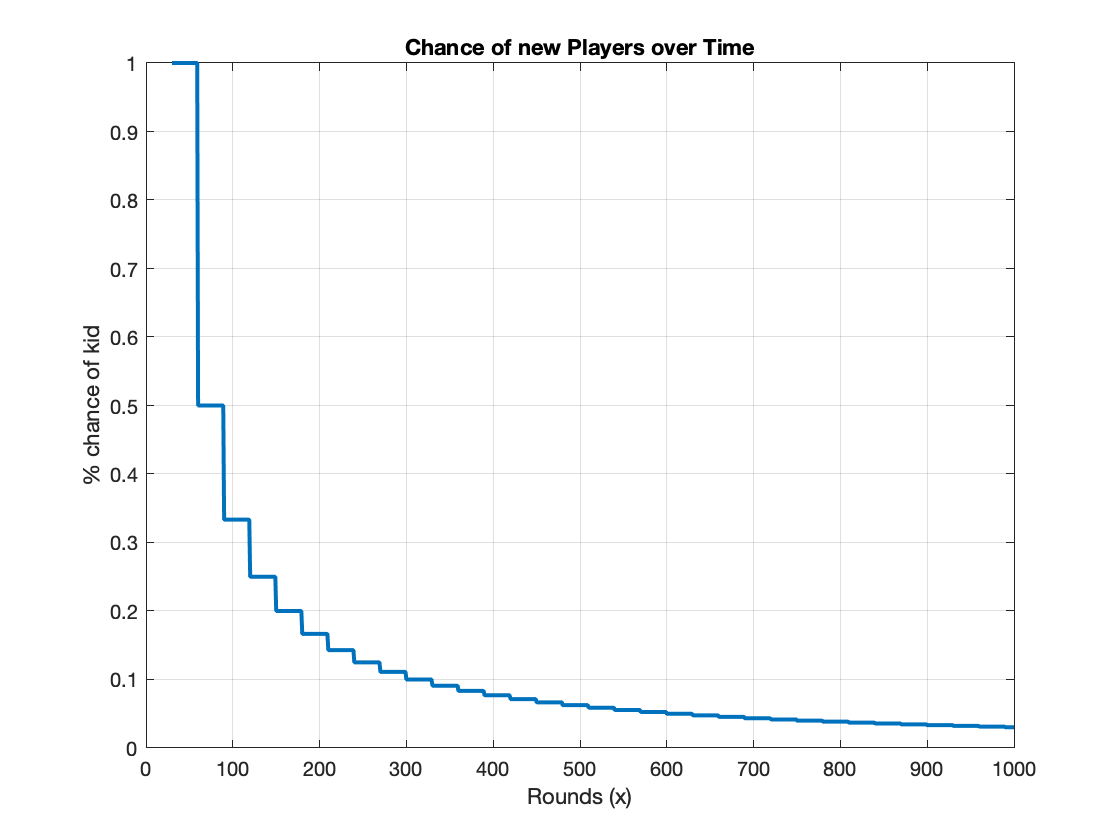

figure
x = 1:1000; %round range
plot(x,1./floor(x/30),'LineWidth',2)
hold on; grid on;
xlabel('Rounds (x)'); ylabel('% chance of kid')
title('Chance of new Players over Time')

### Pure Colors

This section defines the traits of 6 of the 7 Kings of Pure Color.  We know Kuroyukihime has a parent, so she isn't an originator and was created later, and we only have confirmation of Blue, Green, and White being originators.  However, it doesn't seem like that far of a stretch to say most, if not all, of the other Kings were also originators.  The other purpose is to create some players who have more exp and are therefore more interesting to track.

By artificially inflating their exp level, by multiplying the normal player expMax by 1.1, we ensure that these players will likely live and prosper, so we can use them as a guage of the leading edge of Brain Burst play.

There are some problems with colors, but to keep it consistent, they all fit into the HSL color scheme.  Again, more on that in the makePlayer function description itself.  White is cyan colored in terms of color wheel assignment, since she has to have a value, and there isn't a Cyan king, even though there should be one based on the color wheel theory I have here.

## Simulation Preface

This is basically here to save the data to a file.  A dialog box is used so that you have to actively choose what to call it.  Hopefully will implement a warning if you are going to overwrite data.  If no name is entered, it auto-assigns "noName" so that we can still graph trends without pulling errors.